# Miniprojekt 4 - Nøjagtig frekvensmåling

## Indledning

## Formål

## Analyse

!!opstil Krav!!

gFs = 50.1111   %grundfrekvens for begge signaler

gFs = 50.1111

## Opgaven

### Tids- og frekvensanalyse

clear all;
load('signal_IEC60255_50_1111Hz.mat')
fs = signal.fs; %samplingfrekvens på 10 kHz
x1 = signal.x1; %det rene sinus signal
x2 = signal.x2; %signal med 40 harmoniske overtoner
N=length(x1); %antal samples


Først vil de to signaler blive plottet med en tidsakse i intervallet fra 0 til 55 ms.

Periode tiden findes.

ts=1/fs

ts = 1.0000e-04

Nu bestemmes tiden for plottet.

t=0:ts:(N*ts)-ts;


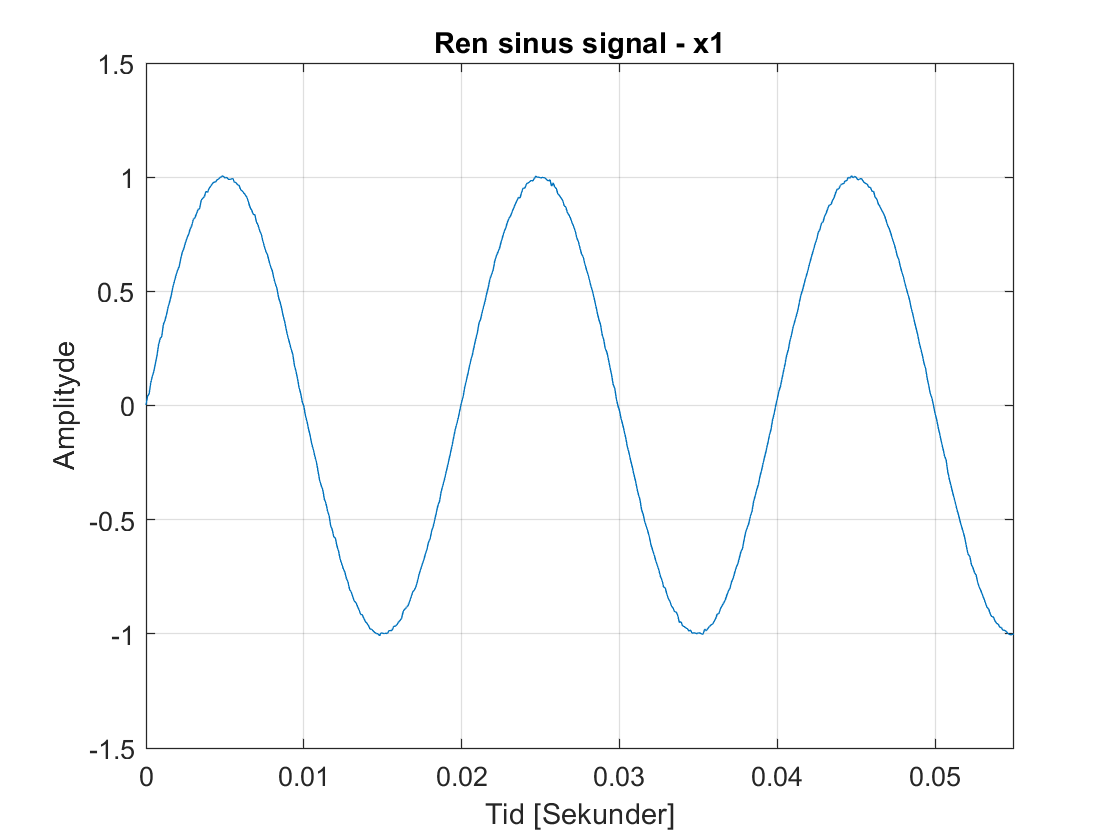

plot(t,x1)
xlim([0 0.055])
title('Ren sinus signal - x1')
grid on
xlabel('Tid [Sekunder]')
ylabel('Amplityde')

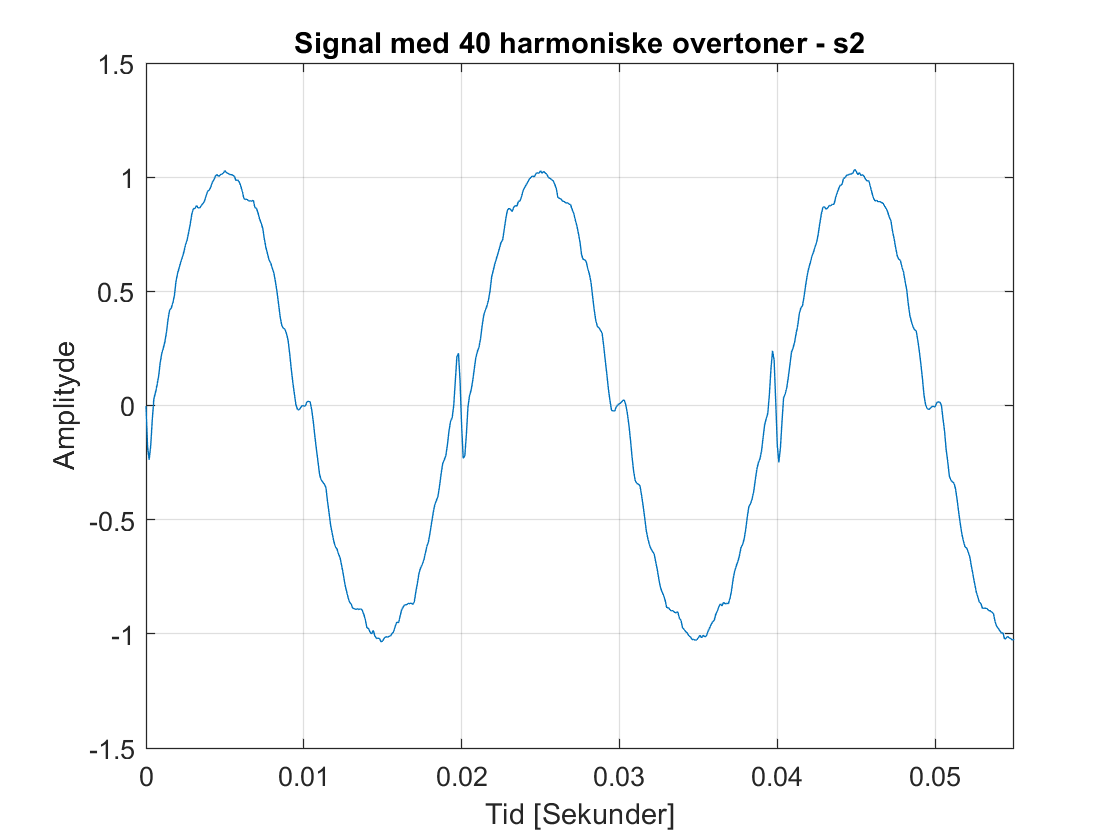


plot(t,x2)
title('Signal med 40 harmoniske overtoner - s2')
grid on
xlim([0 0.055])
xlabel('Tid [Sekunder]')
ylabel('Amplityde')

Nu beregnes DFT for signalerne, samt plot af amplityde spektrene.

Nny = 2^19

Nny = 524288

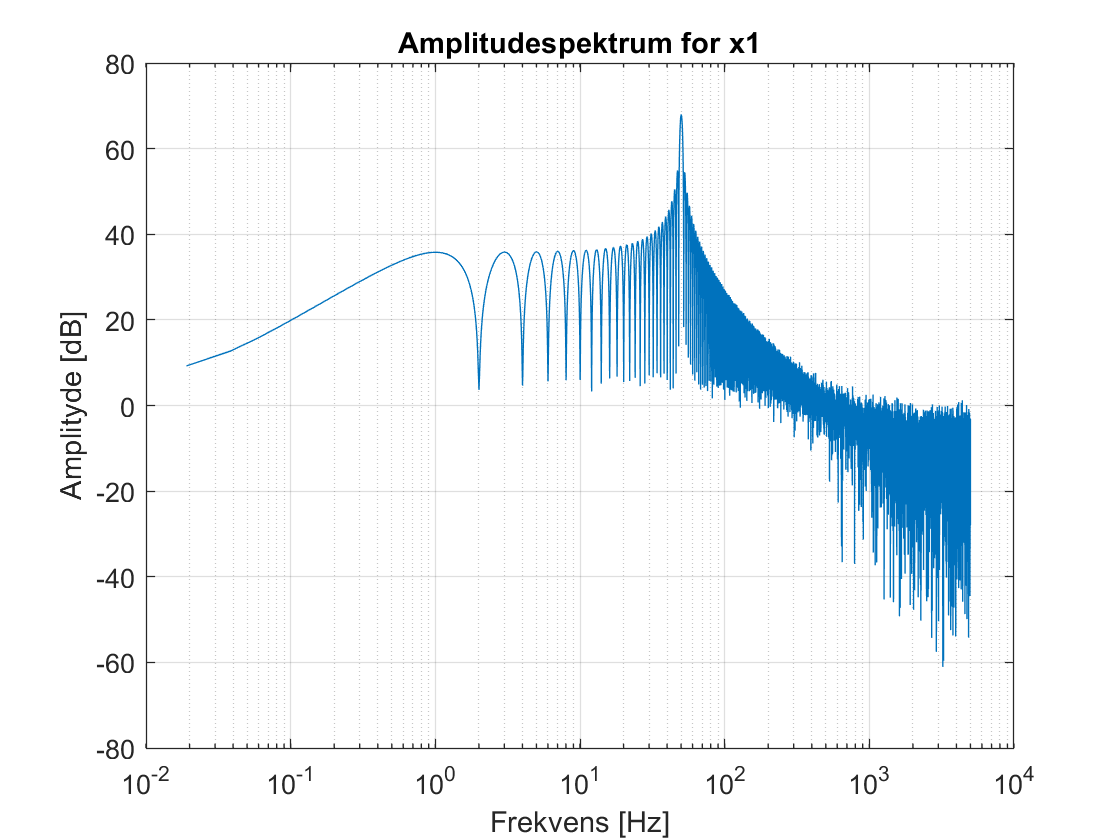

DFTx1 = fft(x1,Nny);
DFTx2 = fft(x2,Nny);
k=0:Nny-1;
f=k*fs/Nny; %frekvensakse
%%!!Find ud af hvad der er meningsfuldt i plottene!!%%
semilogx(f(floor(1:end/2)),real(20*log10(DFTx1(floor(1:end/2)))))
grid on
title('Amplitudespektrum for x1')
xlabel('Frekvens [Hz]')
ylabel('Amplityde [dB]')

[max_amplitude, max_frekvens_bin]=max(DFTx1(floor(1:end/2)))

max_amplitude = 2.1819e+01 - 2.4950e+03i

max_frekvens_bin = 2628

max_frekvens = f(max_frekvens_bin)

max_frekvens = 50.1060

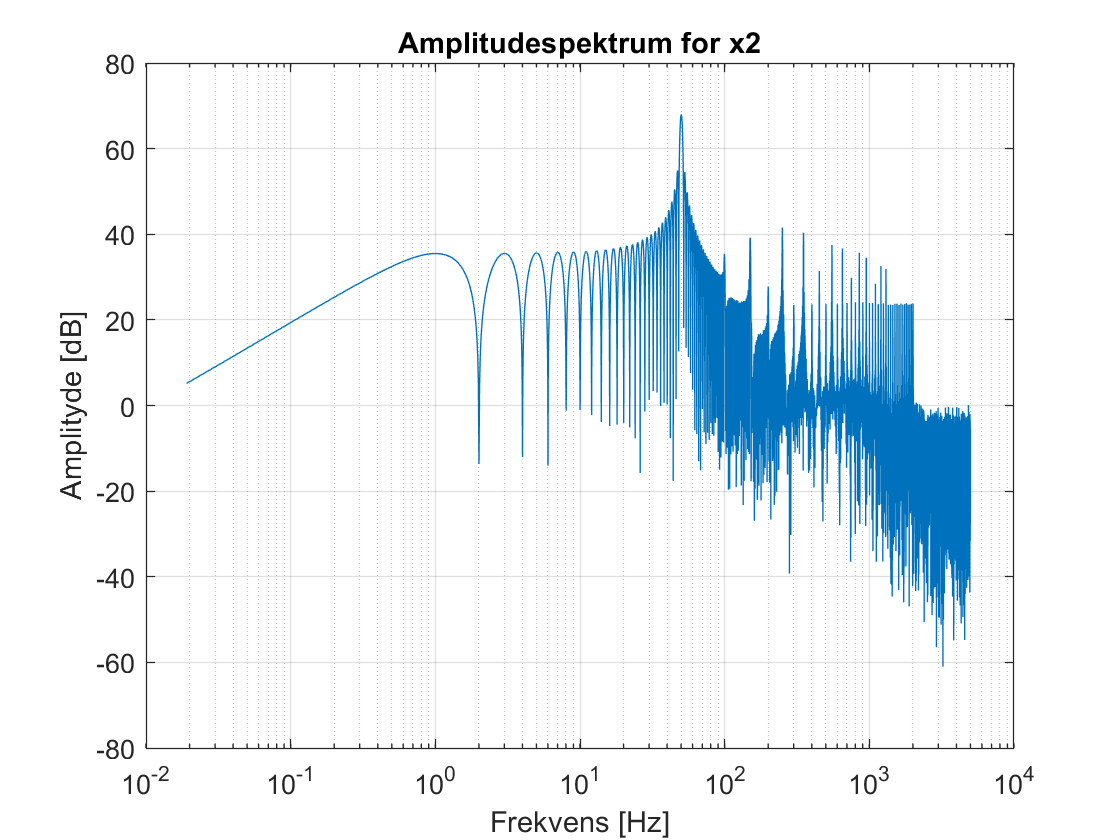

semilogx(f(floor(1:end/2)),real(20*log10(DFTx2(floor(1:end/2)))))
grid on
title('Amplitudespektrum for x2')
xlabel('Frekvens [Hz]')
ylabel('Amplityde [dB]')

frekvensopløsning

deltaf=fs/Nny

deltaf = 0.0191

### Hurtig frekvensestimering med zero crossing

#### Filtrering

#### Zero crossing algoritme